clear; clc;

open_system('rlwatertank')

# Setup environnement

obsInfo = rlNumericSpec([3 1],...
    'LowerLimit',[-inf -inf 0  ]',...
    'UpperLimit',[ inf  inf inf]');
obsInfo.Name = 'observations';
obsInfo.Description = 'integrated error, error, and measured height';
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([1 1]);
actInfo.Name = 'flow';
numActions = actInfo.Dimension(1);

env = rlSimulinkEnv('rlwatertank','rlwatertank/RL Agent',...
    obsInfo,actInfo);

env.ResetFcn = @(in)localResetFcn(in);
Ts = 1.0;
Tf = 200;
rng(0)

# Setup DDPG Agent

## Setup acteur

Choisit la prochaine action à effectuer

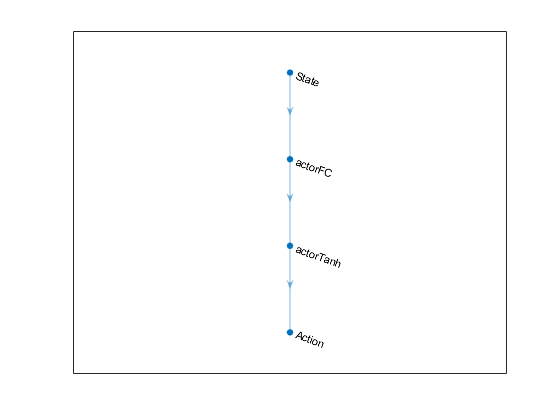

actorNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','State')
    fullyConnectedLayer(3, 'Name','actorFC')
    tanhLayer('Name','actorTanh')
    fullyConnectedLayer(numActions,'Name','Action')
    ];

actorPlot = layerGraph();
actorPlot = addLayers(actorPlot,actorNetwork);

figure
plot(actorPlot)


actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);

actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

## Setup critique

Détermine si l'action effectuée est bonne 

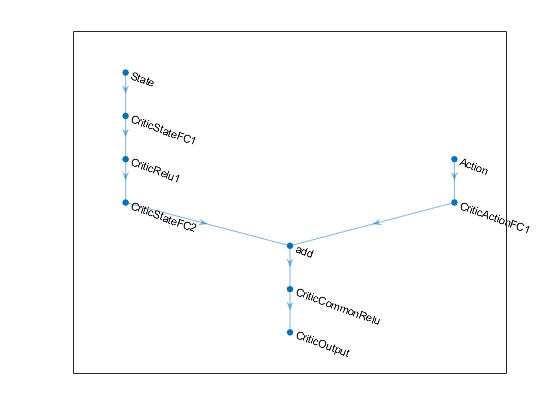

statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','State')
    fullyConnectedLayer(50,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(25,'Name','CriticStateFC2')];
actionPath = [
    featureInputLayer(numActions,'Normalization','none','Name','Action')
    fullyConnectedLayer(25,'Name','CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

figure
plot(criticNetwork)


criticOpts = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);

critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

## Setup agent

agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6); 
agentOpts.NoiseOptions.StandardDeviation = 0.3;
agentOpts.NoiseOptions.StandardDeviationDecayRate = 1e-5;

agent = rlDDPGAgent(actor,critic,agentOpts);

# Setup entrainement

maxepisodes = 5000;
maxsteps = ceil(Tf/Ts); % 200 ici
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',1000);

reinforcementLearningDesigner

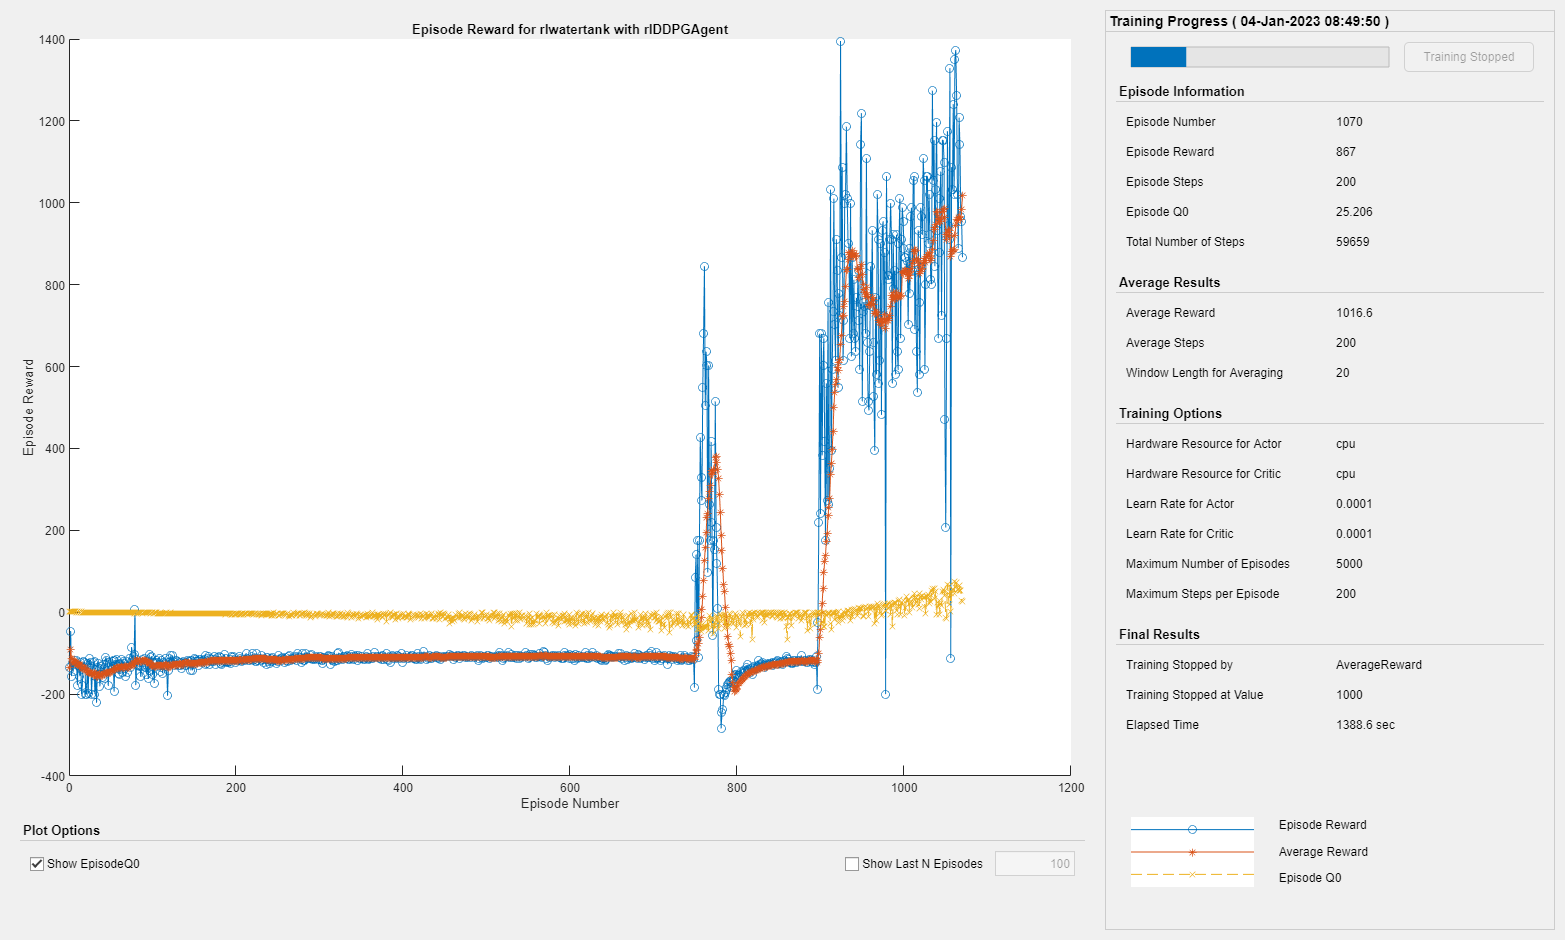

doTraining = true;

if doTraining
    % Train the agent.
   trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('WaterTankDDPG.mat','agent')
end

# Validation

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
experiences = sim(env,agent,simOpts);

#### Fonction reset random

function in = localResetFcn(in)

% randomize reference signal
blk = sprintf('rlwatertank/Desired \nWater Level');
h = 3*randn + 10;
while h <= 0 || h >= 20
    h = 3*randn + 10;
end
in = setBlockParameter(in,blk,'Value',num2str(h));

% randomize initial height
h = 3*randn + 10;
while h <= 0 || h >= 20
    h = 3*randn + 10;
end
blk = 'rlwatertank/Water-Tank System/H';
in = setBlockParameter(in,blk,'InitialCondition',num2str(h));

end